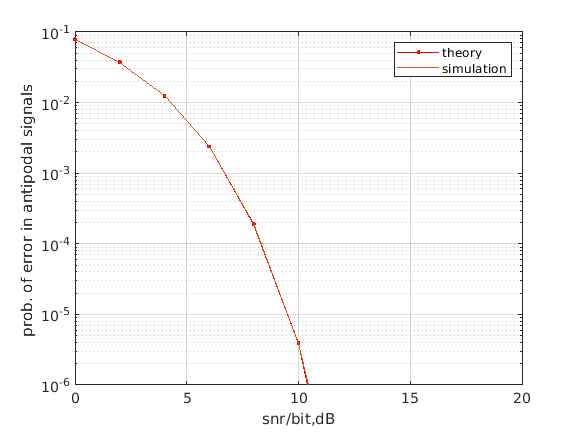

close all;
clear all;
clc;


snr_db=[0 2 4 6 8 10 12 14 16 18 20];
c=snr_db/10;
snr=10.^c;
for l=1:length(snr_db)
    avg_error=0;
    error=0;
    I=10000;
    bits=20000;
    for j=1:I
        s=randsrc(1,bits);
        S=randsrc(1,bits,[1,-i]);
        No=sqrt(10.^-(c)/2);
        o=No(l)*  
        n=No(l)*randn(1,bits);
        
        r=n+s;
        for k=1:length(s)
            if (r(k)>0 && s(k)==-1)||(r(k)<0 && s(k)==1)
                error=error+1;
            end
        end
        error=error/bits;
        avg_error=avg_error+error;
        
    end
    BER(l)=avg_error/I;
end
figure
semilogy(snr_db,BER,'.-r');
axis([0 20 10^-6 10^-1]);
prob.error=0.5.*erfc(sqrt(snr));
hold on
semilogy(snr_db,prob.error,'-');
grid on
legend('theory','simulation');
xlabel('snr/bit,dB');
ylabel('prob. of error in antipodal signals ');

%No is the psd of noise signal
%error is the error of the signal 
%prob.error is the reqired error probability for the signal 
%n is the noise signal 
% s is the input signal